# Image matching

We have a sample of tagged images, tags are saved as xml files from imglabeller. Import these using the getLabels function

root = 'C:\Data\family_photos\tagged';
labels = getLabels(root);

Look at the labels table, and plot one class of the crops.

head(labels)

ans = 8×52 table
                           filename                             clodagh       captainCalamari    buggyBarToy       carSeat       blanket_Camel      hedgehog         stinky          hoops        picnicBlanket      hat_Pink        g_Garden         bunny          rug_Star         totoro       g_Bedroom_C       freddie          buggy          bouncer        bag_Panda      g_LivingRoom    blocks    stove    kitchen    tv    rug_Stripe    livingRoom    blanket_Giraffe    playstationController

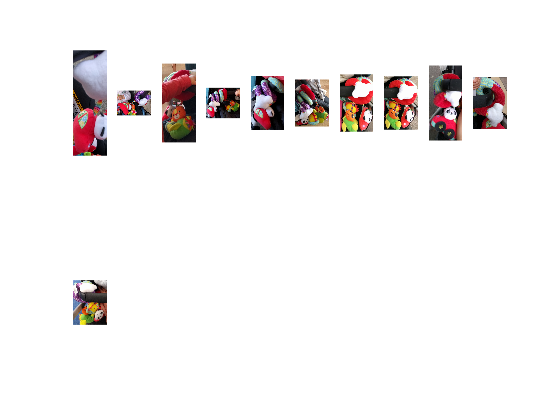

Gallery(labels(:, [1, 4]));

As a first test let's extract all the crops and compute their convnet feature vector

net = alexnet;
layer = 'fc7';

imSize = [227, 227];
[crops, cropLabels] = getCrops(labels);

nCrops = numel(crops);
features = zeros(nCrops, 4096);
for iIm = 1:nCrops
    imResized = imresize(crops{iIm}, imSize);
    features(iIm, :) = getFeatures(imResized, net, layer);
end


distances = pdist2(features, features, 'cosine');